William Andrés Gómez Roa

Señales y Sistemas- Taller 1

# MATLAB - SEÑALES Y SISTEMAS

## 1. Vectores en Matlab:

Un **vector** de longitud N es un arreglo de N números, el cuál puede ser definido en MATLAB asignando el nombre del vector y sus elementos.

Una **matriz **es un arreglo de N filas y M columnas. 

a1 = [1 2 3] % Vector fila de longitud 3.

a1 =      1     2     3


a2= [1;2;3] % Vector columna de longitud 3.

a2 =      1
     2
     3


b1=(1:10) % Vector fila con los numeros desde 1 hasta 10 de uno en uno.

b1 =      1     2     3     4     5     6     7     8     9    10


b2=(1:0.5:5) % Vecotr fila, números del 1 al 5 con saltos de 0.5.

b2 =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


d1=zeros(3,1) %Vector Columna llena con 'zeros' de 3 filas.

d1 =      0
     0
     0


d2=zeros(1,5) %Vector fila 'zeros' con 5 columnas.

d2 =      0     0     0     0     0


e1=ones(3,1) %Vector Columna llena de 'unos' con 3 filas.

e1 =      1
     1
     1


e2= ones(1,10) % Vector Fila de 'ones' con 10 columnas.

e2 =      1     1     1     1     1     1     1     1     1     1


f= rand(10,1) % Vector Columna, con 10 filas y números aleatorios ~[0,1].

f =     0.5310
    0.9012
    0.5406
    0.4320
    0.5427
    0.7124
    0.0167
    0.8009
    0.1425
    0.4785


m=rand(2,5) % Matriz aleatoria de 2 filas y 5 columnas.

m =     0.2568    0.6618    0.2788    0.1951    0.8803
    0.3691    0.1696    0.1982    0.3268    0.4711


## 2. Creación de Vectores

Un vector puede visualizarse de 2 maneras

- plot: Grafíca cada uno de los valores y los une por una linea simulando una señal continua.

- stem: Grafica cada uno de los valores del vector

Ejemplo 1:

% Para el vector x=rand(1,100) realice plot(x) y stem(x).
x=rand(1,100)

x =     0.4040    0.1792    0.9689    0.4075    0.8445    0.6153    0.3766    0.8772    0.7849    0.4650    0.8140    0.8984    0.4292    0.3343    0.5966    0.9020    0.7021    0.3775    0.7350    0.9541    0.5428    0.5401    0.3111    0.0712    0.1820    0.0930    0.4635    0.0093    0.9150    0.6427    0.0014    0.0304    0.2085    0.4550    0.1273    0.0086    0.7271    0.3541    0.7804    0.4367    0.4366    0.0492    0.0496    0.0911    0.5940    0.2411    0.8414    0.8572    0.9636    0.4889


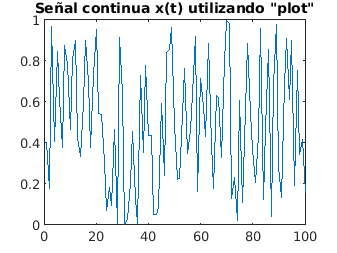


plot(x)
title('Señal continua x(t) utilizando "plot"')

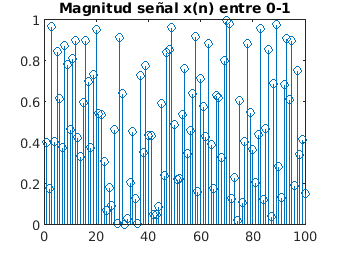


stem(x)
title('Magnitud señal x(n) entre 0-1')

Ejemplo 2:

% SUponga que el vector x contiene la cantidad de horas al díaen la que la
% temperatura supera los 20°C. Dicha medición se realiza cada 2 días y se
% quiere visualizar los datos obtenidos del mes contenido en el vector x. 

x= 18*rand(1,15)

x =    14.7420   11.2486   13.2941   14.4920    1.2100   17.1142    8.9564   13.5926   13.3633   14.9603    2.8170    8.2316   11.1258   16.7793   15.0316


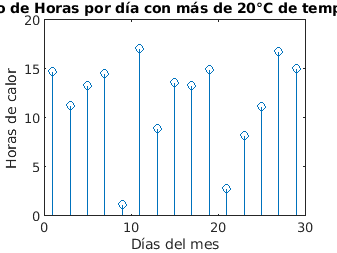

dias = 1:2:30;
stem(dias,x)
xlabel('Días del mes') 
ylabel('Horas de calor') 
title('Número de Horas por día con más de 20°C de temperatura.')

## 3. Transformación de Vectores

### 3.1 Operaciones Globales: +,-,*,/ : Entre un vector y una constante

### 3.2 Operaciones entre vectores: .* , ./ 

### 3.3 Operaciones puntuales

- length(x) :longitud del vector, o la dimension más grande de una MAtriz.

- [fil, col] = size(x) : Número de filas y columnas del vector o matriz. 

- x(i) Valor del vector en la posición 'i'

- x(i,j) VAlor de la matriz en la posicion 'i,j'

clc, clear;
% Sea x un vector, realice una rutina que permita convertir a ceros los
% valores del vector inferiores a 0

%OPCION 1

x= 18*rand(1,15)

x =    16.1176   10.4853   10.4894   15.3887    0.6276   15.9376    7.3392    0.6549   13.4307    2.7869    2.5903   10.9073    4.5807    5.8348    7.2322


L=length(x)

L = 15

for i=1:L
    if x(i) <0
        x(i)=0;
    end
end

%OPCION 2

I = x>0 % posciones donde x>0

I = 1×15 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


y= x.*I % se conservan x>0 los otros se hacen 0

y =    16.1176   10.4853   10.4894   15.3887    0.6276   15.9376    7.3392    0.6549   13.4307    2.7869    2.5903   10.9073    4.5807    5.8348    7.2322


## 4. Construcción y Visualización de Señales

Para la construcción de señales discretas es necesario especificar el **soporte de la señal** (intervalo de n) , el cual debe ser un subconjunto de los enteros. 

Ejemplo: **Creación de una señal sinudoidal discreta de longitud L, A es la amplitud, OMEGA=2*pi*k/N es la frecuencia, N es el período (discreto) y PHI es la fase . **

**n=1:L-1;**

**x=A*sin((OMEGA)*n + PHI)**

### **EJERCICIO 1:**

% CREE Y VISUALIZE UNA SEÑAL SINUSOIDAL CAUSAL DE LONGITUD 100, PERIODO 10
% Y AMPLITUD 5. Pruebe ue pasa para diferentes valores de k.
k=1

k = 1


A=5;
L=101;
N=10;
OMEGA=2*pi*k/N

OMEGA = 0.6283

n=1:L-1

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



X= A*sin(OMEGA*n)

X =     2.9389    4.7553    4.7553    2.9389    0.0000   -2.9389   -4.7553   -4.7553   -2.9389   -0.0000    2.9389    4.7553    4.7553    2.9389    0.0000   -2.9389   -4.7553   -4.7553   -2.9389   -0.0000    2.9389    4.7553    4.7553    2.9389    0.0000   -2.9389   -4.7553   -4.7553   -2.9389   -0.0000    2.9389    4.7553    4.7553    2.9389    0.0000   -2.9389   -4.7553   -4.7553   -2.9389   -0.0000    2.9389    4.7553    4.7553    2.9389    0.0000   -2.9389   -4.7553   -4.7553   -2.9389   -0.0000


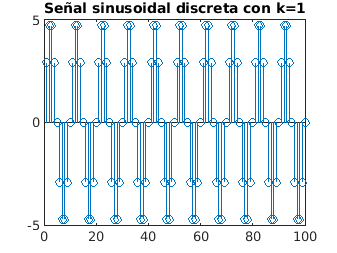

stem(n, X)
title('Señal sinusoidal discreta con k=1')

k=2

k = 2

OMEGA=2*pi*k/N

OMEGA = 1.2566

X= A*sin(OMEGA*n)

X =     4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000


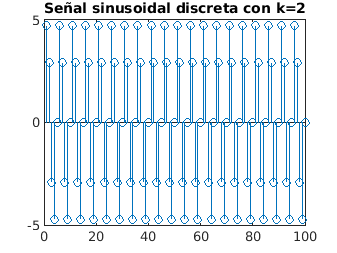

stem(n, X)
title('Señal sinusoidal discreta con k=2')

k=4

k = 4

OMEGA=2*pi*k/N

OMEGA = 2.5133

X= A*sin(OMEGA*n)

X =     2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000    2.9389   -4.7553    4.7553   -2.9389   -0.0000


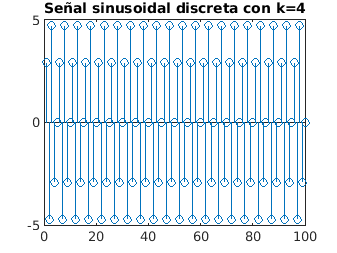

stem(n, X)
title('Señal sinusoidal discreta con k=4')

K al ser un entero hace que la señal sea peridica, y ademas es directamente proporcional a la frecuencia por tanto esta aumenta cuando k aumenta.

### EJERCICIO 2: 

Cree 3 señales sinusoidales de longitud 100 y periodos, 2,3 y 5, respectivamente. Visualice la señal generada por la suma de las 3 señales sinusoidales 

N1=2;
N2=3;
N3=5;
n=1:100;

OMEGA_1=2*pi/N1

OMEGA_1 = 3.1416

OMEGA_2=2*pi/N2

OMEGA_2 = 2.0944

OMEGA_3=2*pi/N3

OMEGA_3 = 1.2566


x1=  A*sin(OMEGA_1*n)

x1 = 1.0e-12 *

    0.0006   -0.0012    0.0018   -0.0024    0.0031   -0.0037    0.0043   -0.0049    0.0055   -0.0061    0.0245   -0.0073   -0.0098   -0.0086    0.0269   -0.0098   -0.0074   -0.0110    0.0294   -0.0122   -0.0049   -0.0490    0.0318   -0.0147   -0.0025    0.0196    0.0343   -0.0171   -0.0000   -0.0539    0.0367   -0.0196    0.0024    0.0147    0.0392   -0.0220    0.0049   -0.0588    0.0416   -0.0245    0.0784    0.0098    0.0441   -0.0980    0.0098   -0.0637   -0.0245   -0.0294    0.0833    0.0049


x2=  A*sin(OMEGA_2*n)

x2 =     4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301   -0.0000    4.3301   -4.3301


x3=  A*sin(OMEGA_3*n)

x3 =     4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000    4.7553    2.9389   -2.9389   -4.7553   -0.0000



SUMA= x1 +x2 +x3

SUMA =     9.0854   -1.3912   -2.9389   -0.4252   -4.3301    4.7553    7.2691   -7.2691   -4.7553    4.3301    0.4252    2.9389    1.3912   -9.0854   -0.0000    9.0854   -1.3912   -2.9389   -0.4252   -4.3301    4.7553    7.2691   -7.2691   -4.7553    4.3301    0.4252    2.9389    1.3912   -9.0854   -0.0000    9.0854   -1.3912   -2.9389   -0.4252   -4.3301    4.7553    7.2691   -7.2691   -4.7553    4.3301    0.4252    2.9389    1.3912   -9.0854   -0.0000    9.0854   -1.3912   -2.9389   -0.4252   -4.3301


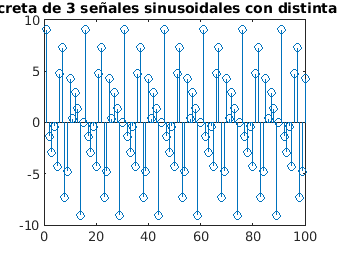

stem(n, SUMA)
title('Suma discreta de 3 señales sinusoidales con distinta frecuencia')

## 5. Energía y Potencia de señales

#### Grafique la potencia instantanea de la señal x, para el intervalo discreto n=1:50.

clc, clear;
n=1:50

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x= 2*sin((2*pi/8)*n)

x =     1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000



p=abs(x.^2)

p =     2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000    2.0000    0.0000    2.0000    4.0000


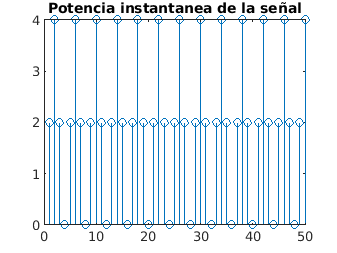


stem(n,p)
title('Potencia instantanea de la señal')

####  Calcule el valor de la energía de la señal anterior.

E=sum(p)

E = 102.0000

La energía total sería la suma desde -inf hasta inf de la potencia instantanea.

E=102.00